# Numerical solution to the flow problem

set_demo_defaults;

### Governing equations

Here we are solving the dimensionless instantaneous flow problem for constant porosity, given by

1) $-\nabla_D^2h_D+h_D = z_D$     on  $z_D \in\left[0,\,H_D\right]$,

2) $-\nabla_D^2u_D=h_D-z_D$     on  $z_D \in\left[0,\,H_D\right]$.

where $H_D=H/\delta$ is the dimensionles domain height. The boundary conditions are no flow for both the solid and the melt:

$\left.\frac{\mbox{d}h_D}{\mbox{d}z_D}\right|_0=\left.\frac{\mbox{d}h_D}{\mbox{d}z_D}\right|_{H_D}=0$   and     $\left.\frac{\mbox{d}u_D}{\mbox{d}z_D}\right|_0=\left.\frac{\mbox{d}u_D}{\mbox{d}z_D}\right|_{H_D}=0$.

The fluid fux relative to the solid and the solid velocity are given by

$q=-\nabla h $ and $v=-\nabla u$.

The only dimensionless governing parameter in this problem is the dimensionles domain height, $H_D=H/\delta$.

HD = 5;

### Analytic solution

The analytic solution for the potentials and the overpressure are given by

$h_D(z_D)=z+\frac{e^{-H_D}-1}{e^{H_D}-e^{-H_D}}e^z+\frac{e^{H_D}-1}{e^{H_D}-e^{-H_D}}e^{-z}$,

$u_D(z_D)=-z-\frac{e^{-H_D}-1}{e^{H}-e^{-H}}e^z-\frac{e^{H_D}-1}{e^{H}-e^{-H}}e^{-z}$,

$p_D=\frac{e^{-H_D}-1}{e^{H}-e^{-H_D}}e^z+\frac{e^{H_D}-1}{e^{H_D}-e^{-H_D}}e^{-z}$.

The associated flux and velocity are given by

$q_D(z_D) = -1-\frac{e^{-H_D}-1}{e^{H_D}-e^{-H_D}}e^z+\frac{e^{H_D}-1}{e^{H_D}-e^{-H_D}}e^{-z}$,

$v_D(z_D)=1+\frac{e^{-H_D}-1}{e^{H}-e^{-H}}e^z-\frac{e^{H_D}-1}{e^{H}-e^{-H}}e^{-z}$.

zDa = linspace(0,HD,1e3);
% coefficients
c1 = @(H) (exp(-H)-1)./(exp(H)-exp(-H));
c2 = @(H) (exp(H)-1)./(exp(H)-exp(-H));
% potentials
hDa = @(z,H) z + c1(H).*exp(z) + c2(H).*exp(-z);
uDa = @(z,H) -z - c1(H).*exp(z) - c2(H).*exp(-z);
% overpressure
pDa = @(z,H) c1(H).*exp(z) + c2(H).*exp(-z);
% flux & velocity
qDa = @(z,H) -1 - c1(H).*exp(z) + c2(H).*exp(-z);
vDa = @(z,H) 1 + c1(H).*exp(z) - c2(H).*exp(-z);

## Numerical solution

We use the same numerical grid and basic operators for both equations.

Grid.xmin = 0; Grid.xmax = HD; Grid.Nx = 50;
Grid = build_grid(Grid); 
zDc = Grid.xc; zDf = Grid.xf;
[D,G,C,I,M] = build_ops(Grid);

However, the system matrix, `L`, and the r.h.s. vector, `fs`, and quantities related to the boundary conditions may be different. Therefore we will attach 'h' and 'u' to them to identify the appropriate equation

### Solving the mod. Helmholtz equation for `h`

First we solve the mod. Helmholtz equation for the overpressure head. We have not solved this type of equation before, but we can build the required the linear operators from the operators provided by build_grid as follows

L_h = -D*G+I;
fs_h = zDc;

Due to the head formulation, the boundary condtions are natural

BC.h.dof_dir   = [];
BC.h.dof_f_dir = [];
BC.h.g         = [];
BC.h.dof_neu   = [];
BC.h.dof_f_neu = [];
BC.h.qb        = [];

[B_h,N_h,fn_h] = build_bnd(BC.h,Grid,I);

The numerical solution of the linear system is always the same

%% Solve boundary value problem
hD = solve_lbvp(L_h,fs_h+fn_h,B_h,BC.h.g,N_h);
pD = hD-zDc;

### Solve the Poisson problem for u

Once the overpressure head is known we can solve the Poisson equation for the velocity potential. This equation has two interesting aspects:

- Natural BC's leave an undetermined constant.

- The compatability condition together with natural BC's requires that the operpressure sums to zero.

The compatability condition can be verified

sum(pD)

ans = 1.2523e-13

and is satisfied up to rounding error due to the **discrete conservation** of our numerical method. 

The undetermined constant can be dealt with by simply applying a Dirichlet BC and setting the head at the bottom to zero. The natral boundary condition will will be imposed because the compatability condition requires it! As such we will solve the problem with the following BC's

$h_1 = h(\Delta z/2)$  and  $\left.\frac{\mbox{d}u_D}{\mbox{d}z_D}\right|_{H_D}=0$.

Here se set the first cell center to the analytic solution.

L_u = -D*G;
fs_u = pD;

From a physical point of view the boundary conditions are no flow and hence natural. But the p

BC.u.dof_dir   = [Grid.dof_xmin];
BC.u.dof_f_dir = [Grid.dof_f_xmin];
BC.u.g         = uDa(zDc(BC.u.dof_dir),HD);
BC.u.dof_neu   = [];
BC.u.dof_f_neu = [];
BC.u.qb        = [];

[B_u,N_u,fn_u] = build_bnd(BC.u,Grid,I);

The numerical solution of the linear system is always the same

%% Solve boundary value problem
uD = solve_lbvp(L_u,fs_u+fn_u,B_u,BC.u.g,N_u);

### Flux and velocity computation

Now that the potentials are known the relative fluid flux and the solid velocity can be computed. 

First we need to define the 'flux', i.e., the relation between the potential and the flux/velocity. Because the porosity is constant, these expressions are identical.

flux_h = @(h) -G*h;
flux_u = @(u) -G*u;

The residuals of the two equations differe because the linear operators differ.

res_h = @(h,cell) L_h(cell,:)*h - fs_h(cell); 
res_u = @(u,cell) L_u(cell,:)*u - fs_u(cell); 

Once the fluxes and the residuals are defined the `qD` and `vD` can be computed using `comp_flux_gen.m`.

qD = comp_flux_gen(flux_h,res_h,hD,Grid,BC.h);
vD = comp_flux_gen(flux_u,res_u,uD,Grid,BC.u);

### Compare with the analytic solution

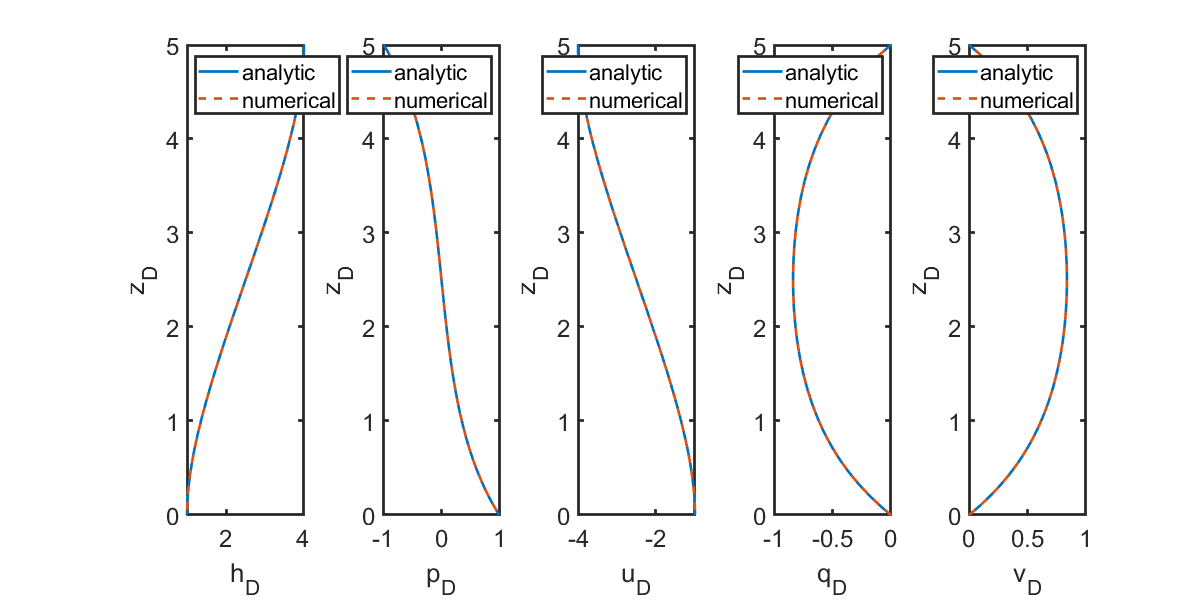

figure('position',[10 10 1200 600])
%% Plotting and post-processing
subplot 151
plot(hDa(zDa,HD),zDa,'linewidth',2), hold on
plot(hD,zDc,'--','linewidth',2)
xlabel('h_D','fontsize',22)
ylabel('z_D','fontsize',22)
legend('analytic','numerical','location','northwest')
set(gca,'fontsize',18)

subplot 152
plot(pDa(zDa,HD),zDa,'linewidth',2), hold on
plot(pD,zDc,'--','linewidth',2)
xlabel('p_D','fontsize',22)
ylabel('z_D','fontsize',22)
legend('analytic','numerical','location','northeast')
set(gca,'fontsize',18)

subplot 153
plot(uDa(zDa,HD),zDa,'linewidth',2), hold on
plot(uD,zDc,'--','linewidth',2)
xlabel('u_D','fontsize',22)
ylabel('z_D','fontsize',22)
legend('analytic','numerical','location','northeast')
set(gca,'fontsize',18)

subplot 154
plot(qDa(zDa,HD),zDa,'linewidth',2), hold on
plot(qD,zDf,'--','linewidth',2)
xlabel('q_D','fontsize',22)
ylabel('z_D','fontsize',22)
legend('analytic','numerical','location','northeast')
set(gca,'fontsize',18)

subplot 155
plot(vDa(zDa,HD),zDa,'linewidth',2), hold on
plot(vD,zDf,'--','linewidth',2)
xlabel('v_D','fontsize',22)
ylabel('z_D','fontsize',22)
legend('analytic','numerical','location','northeast')
set(gca,'fontsize',18)